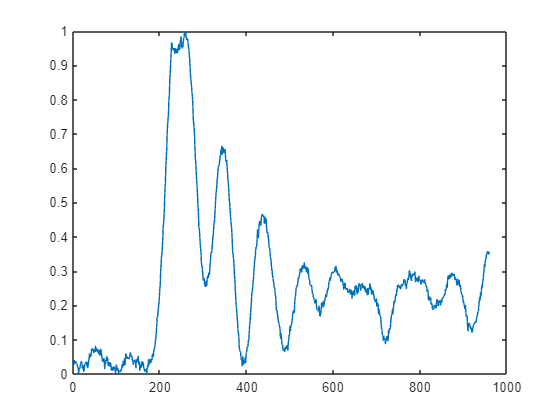

plot(score)

x = 1:960

x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


y(x) = 0.05

y =     0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500


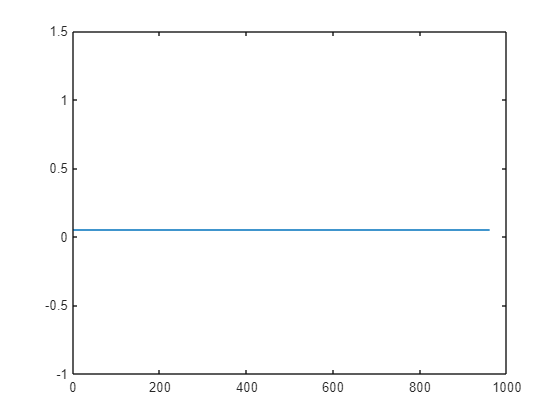

plot(y)

output = score > 0.05

output = 1×960 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   1   1   1   1   1   1   1   1   1   1


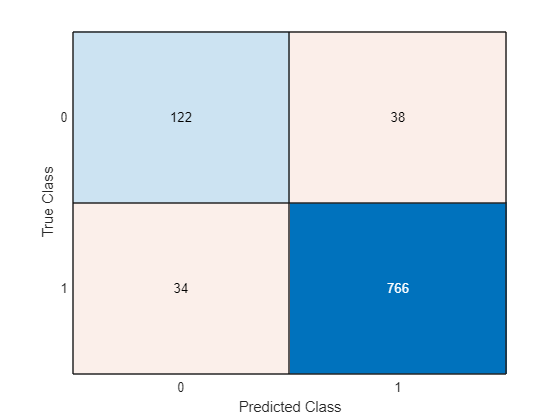

confusionchart(label,double(output))

tp = 766,fp = 38, fn = 34, tn = 122;

tp = 766

fp = 38

fn = 34

Precisison = tp/(tp+fp)

Precisison = 0.9527

Recall = tp/(tp+fn)

Recall = 0.9575

Accuracy = (tp+tn)/960

Accuracy = 0.9250

f1_score = 2*tp/(2*tp+fp+fn)

f1_score = 0.9551

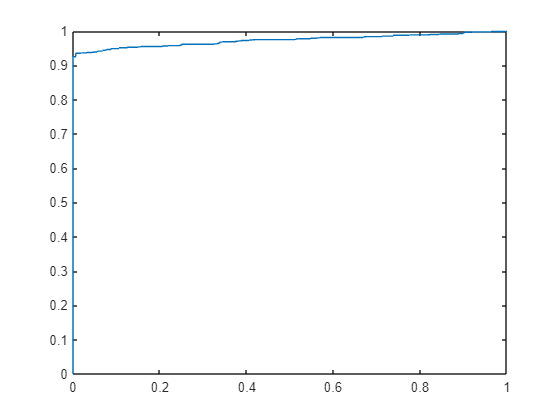

[tpr,frp,thresholds] = roc(label,score);
plot(frp,tpr)

AUC = trapz(frp,tpr)

AUC = 0.9729